# Exercise H3:

clear all; clc; close all;

Solution with 6 points gives

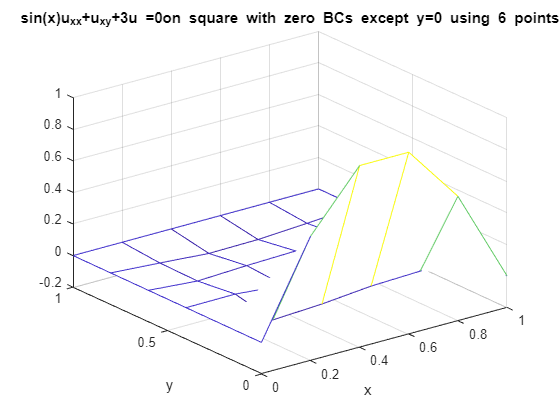

numpts = 6;
[xnew,ynew,sol_new] = FD_2D_func(numpts);


figure; 
mesh(xnew,ynew,sol_new);
xlabel('x')
ylabel('y')
title(['sin(x)u_{xx}+u_{xy}+3u =0' ...
    'on square with zero BCs except y=0 using ' num2str(numpts) ' points'])

Then we can see the solution with 20 points

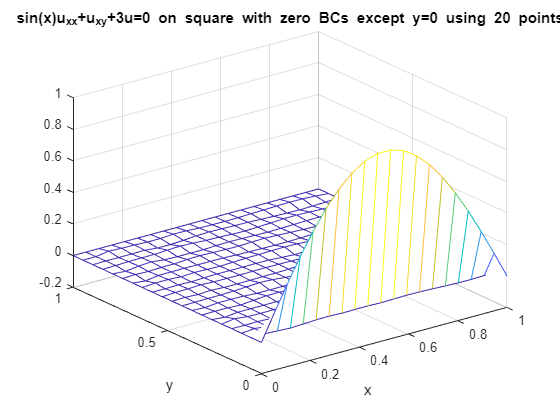

%% 20 points
numpts = 20;
[xnew,ynew,sol_new] = FD_2D_func(numpts);


figure; 
mesh(xnew,ynew,sol_new);
xlabel('x')
ylabel('y')
title(['sin(x)u_{xx}+u_{xy}+3u=0 ' ...
    'on square with zero BCs except y=0 using ' num2str(numpts) ' points'])

And with 60 points

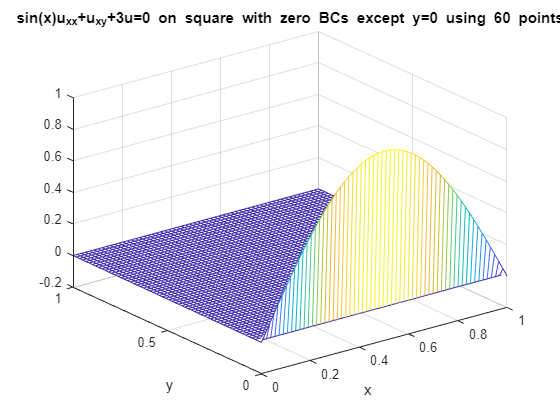

%% 60 points
numpts = 60;
[xnew,ynew,sol_new] = FD_2D_func(numpts);


figure; 
mesh(xnew,ynew,sol_new);
xlabel('x')
ylabel('y')
title(['sin(x)u_{xx}+u_{xy}+3u=0 ' ...
    'on square with zero BCs except y=0 using ' num2str(numpts) ' points'])

The solution seems to get better with a finer grid. But I did not plot the true solution compared to the numerical solution to be sure of this. 

Let's define a function to help us try different point easily:

function [x,y,sol] = FD_2D_func(numpts)
N = numpts; % number of grid points in x and y directions, same in both.
m = N - 2; % number of interior points

% -------------------------------------------------------------------------
% Define the grid:
% -------------------------------------------------------------------------
x1 = 0;
xN = 1;
y1 = 0;
yN = 1;
% -------------------------------------------------------------------------
% Determine the stepsize:
% -------------------------------------------------------------------------
h       = (xN-x1)/(N-1);

%--------------------------------------------------------------------------
% Helper functions
%--------------------------------------------------------------------------
a_fun = @(x) 3-2*(sin(x))/h.^2;
b_fun = @(x) sin(x)/h.^2;
c = 1/(4*h.^2);
% -------------------------------------------------------------------------
% We'll just use the same stepsize in x and y 
% Build the xvector of grid points:
% -------------------------------------------------------------------------
x       = x1:h:xN;
y       = y1:h:yN;
% -------------------------------------------------------------------------
% Define the solution matrix and plug in BCs.
% -------------------------------------------------------------------------
sol_FD         = zeros(N,N);
sol_FD(:,1)    = 0; % Enforcing the left side is u=0
sol_FD(:,end)  = 0; % Enforcing right side u=0
sol_FD(end,:)  = 0; % Enforcing the top u=0
sol_FD(1,:)    = sin(pi*x); % Enforcing the bottom BC u(x,0)=sin(pi*x)
% -------------------------------------------------------------------------
% -------------------------------------------------------------------------
% Build the matrix A:
% -------------------------------------------------------------------------
ind = 1:m^2-3;
inner_supsub_diag = -c.*(mod(ind,4)~=1)';
ind = 1:m^2-5;
outer_supsub_diag = c.*(mod(ind,4)~=0)';
x_rep = repmat(x(2:end-1), m, 1);
x_rep = x_rep(:);
% Build the main structure of the matrix
A = a_fun(x_rep).*eye(m^2,m^2) ...  % main diagonal 
    + 1*diag(inner_supsub_diag,3) ... % yellow on notes
    + 1*diag(inner_supsub_diag,-3) ... % yellow 
    + 1*diag(outer_supsub_diag,5) ... % light blue
    + 1*diag(outer_supsub_diag,-5) ... % light blue
    + diag(b_fun(x_rep(1:m^2-m)).*ones(m^2-m,1),m) ... % dark blue
    + diag(b_fun(x_rep(m+1:m^2)).*ones(m^2-m,1),-m);  % red

% -------------------------------------------------------------------------
% Build the RHS vector
% -------------------------------------------------------------------------
RHS_vec     = zeros(m^2,1);
% Adjust the entries that have the BCs in them 1, m+1, 2*m+1, etc.  Note
% that the book uses a different ordering of the EQUATIONS that is not as 
% directly compatible with the (:) notation.

for k=1:m
    RHS_vec((k-1)*m + 1)  = -((sin(k)-sin(k+1))./4);
end

% -------------------------------------------------------------------------
% Solve for the solution at the interior points
% -------------------------------------------------------------------------
u_interior                      = A\RHS_vec(:);
u_interior                      = reshape(u_interior,m,m); 
sol_FD(2:(end-1),2:(end-1))     = u_interior;
sol = sol_FD;
end